# SNW_VFI_PARAM Tiny Solution Analysis

This is the example vignette for function: [**snw_vfi_main**](https://github.com/FanWangEcon/PrjOptiSNW/tree/master/PrjOptiSNW/params/snw_vfi_main.m) from the [**PrjOptiSNW Package**](https://fanwangecon.github.io/PrjOptiSNW/)**. **This function solves for policy function fully iteratively using matlab minimizer.

## Test SNW_VFI_MAIN Defaults

Call the function with defaults.

mp_param = snw_mp_param('default_tiny');
[V_VFI,ap_VFI,cons_VFI,exitflag_VFI] = snw_vfi_main(mp_param);

SNW_VFI_MAIN: Finished Age Group:7 of 7
SNW_VFI_MAIN: Finished Age Group:6 of 7
SNW_VFI_MAIN: Finished Age Group:5 of 7
SNW_VFI_MAIN: Finished Age Group:4 of 7
SNW_VFI_MAIN: Finished Age Group:3 of 7
SNW_VFI_MAIN: Finished Age Group:2 of 7
SNW_VFI_MAIN: Finished Age Group:1 of 7
Elapsed time is 85.021547 seconds.
Completed SNW_VFI_MAIN;SNW_MP_PARAM=;default_tiny;SNW_MP_CONTROL=;default_base


V_VFI

V_VFI = V_VFI(:,:,1,1,1,1) =

   -4.6974   -2.1640    1.0464    1.9590    2.2352    2.3407    2.3885    2.4130    2.4268    2.4352
   -3.7655   -1.7368    1.0270    1.8465    2.0955    2.1908    2.2338    2.2558    2.2681    2.2756
   -3.5149   -1.5330    0.9448    1.6743    1.8928    1.9761    2.0134    2.0323    2.0429    2.0493
   -4.1261   -1.5899    0.7967    1.4275    1.6063    1.6734    1.7028    1.7174    1.7254    1.7303
   -4.9289   -1.6190    0.6419    1.1358    1.2587    1.3014    1.3189    1.3278    1.3328    1.3359
   -3.7423   -0.5954    0.6982    0.9129    0.9761    0.9976    1.0073    1.0122    1.0150    1.0167
   -3.6666   -0.5197    0.7295    0.9158    0.9640    0.9815    0.9893    0.9932    0.9955    0.9968


V_VFI(:,:,2,1,1,1) =

   -3.0598   -1.4684    1.1198    1.9686    2.2372    2.3412    2.3887    2.4130    2.4268    2.4352
   -2.3986   -1.1130    1.1012    1.8565    2.0975    2.1913    2.2340    2.2558    2.2682    2.2757
   -2.2868   -1.0115    1.0128    1.6

cons_VFI

cons_VFI = cons_VFI(:,:,1,1,1,1) =

    0.2758    0.4896    1.6678    4.8913   11.1448   21.4465   36.8113   58.2531   86.7851  123.4580
    0.3418    0.5209    1.7294    4.9524   11.2058   21.5075   36.8723   58.3141   86.8461  123.5365
    0.4217    0.5992    1.8050    5.0274   11.2807   21.5823   36.9471   60.8396   94.1985  136.9620
    0.3769    0.5917    1.7978    5.0202   11.9029   25.9156   49.4326   81.9709  125.6516  179.3622
    0.2143    0.4957    2.0455    8.2725   20.7322   37.2891   60.4728   91.2973  140.3050  216.5398
    0.2143    0.6580    3.4356    9.7873   25.6842   46.9324   86.0147  130.9132  203.4919  280.7856
    0.2143    0.6580    3.6963   11.8723   27.7693   53.9694   93.0517  147.5936  220.1722  313.3645


cons_VFI(:,:,2,1,1,1) =

    0.3874    0.5655    1.7724    4.9950   11.2484   21.5500   36.9148   58.3566   86.8886  123.5616
    0.4802    0.6567    1.8609    5.0828   11.3360   21.6376   37.0024   58.4442   86.9762  123.6663
    0.5350    0.7679    1.96

ap_VFI

ap_VFI = ap_VFI(:,:,1,1,1,1) =

         0    0.2278    2.0850    7.0370   16.6804   32.5789   56.2963   89.3964  133.4431  189.9625
         0    0.2606    2.0850    7.0370   16.6804   32.5789   56.2963   89.3964  133.4431  189.9449
         0    0.2606    2.0850    7.0370   16.6804   32.5789   56.2963   86.9457  126.1654  176.5942
    0.0372    0.2606    2.0850    7.0370   16.0510   28.2384   43.8037   65.8073   94.7052  134.1868
         0    0.1624    1.6508    3.5998    7.0370   16.6804   32.5789   56.2963   79.8672   96.8247
         0         0    0.2606    2.0850    2.0850    7.0370    7.0370   16.6804   16.6804   32.5789
         0         0         0         0         0         0         0         0         0         0


ap_VFI(:,:,2,1,1,1) =

         0    0.2606    2.0850    7.0370   16.6804   32.5789   56.2963   89.3964  133.4431  189.9623
         0    0.2606    2.0850    7.0370   16.6804   32.5789   56.2963   89.3964  133.4431  189.9451
    0.0578    0.2606    2.0850    

## Tiny Param Results Define Frames

Define the matrix dimensions names and dimension vector values. Policy and Value Functions share the same ND dimensional structure.

% Grids:
age_grid = [19, 28:16:92, 100];
agrid = mp_param('agrid')';
eta_grid = mp_param('eta_grid')';
edu_grid = [0,1];
marry_grid = [0,1];
kids_grid = (1:1:mp_param('n_kidsgrid'))';
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
cl_mp_datasetdesc = {};
cl_mp_datasetdesc{1} = containers.Map({'name', 'labval'}, {'age', age_grid});
cl_mp_datasetdesc{2} = containers.Map({'name', 'labval'}, {'savings', agrid});
cl_mp_datasetdesc{3} = containers.Map({'name', 'labval'}, {'shock', eta_grid});
cl_mp_datasetdesc{4} = containers.Map({'name', 'labval'}, {'edu', edu_grid});
cl_mp_datasetdesc{5} = containers.Map({'name', 'labval'}, {'marry', marry_grid});
cl_mp_datasetdesc{6} = containers.Map({'name', 'labval'}, {'kids', kids_grid});

## Analyze Savings and Shocks

First, analyze Savings Levels and Shocks, Aggregate Over All Others, and do various other calculations.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('cl_st_xtitle') = {'Savings States, a'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rowvar_name') = 'z=';
mp_support_graph('it_legend_select') = 3; % how many shock legends to show
mp_support_graph('st_rounding') = '6.2f'; % format shock legend

#### MEAN(VAL(A,Z)), MEAN(AP(A,Z)), MEAN(C(A,Z))

Tabulate value and policies along savings and shocks:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [1,4,5,6,3,2];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(VAL(A,Z))", V_VFI, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(VAL(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings    mean_shock__0_72413    mean_shock__0_36206    mean_shock_0    mean_shock_0_36206    mean_shock_0_72413
    _____    _______    ___________________    ___________________    ____________    __________________    __________________

      1            0          -5.4151                -4.5369            -3.8356            -3.3221               -2.9166      
      2      0.26063          -2.3705                -1.9859            -1.6414            -1.3293               -1.0173      
      3        2.085          0.46462                0.52217            0.58804            0.66043                0.7364      
      4        7.037           1.2695                  1.278             1.28

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(AP(A,Z))", ap_VFI, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(AP(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings    mean_shock__0_72413    mean_shock__0_36206    mean_shock_0    mean_shock_0_36206    mean_shock_0_72413
    _____    _______    ___________________    ___________________    ____________    __________________    __________________

      1            0          0.01785               0.041942            0.059604           0.079515              0.19785      
      2      0.26063          0.14294                 0.1455             0.15365            0.21784              0.37368      
      3        2.085           1.4472                 1.4472              1.4472             1.4472               1.4472      
      4        7.037           4.7773                 4.7773              4.77

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(C(A,Z))", cons_VFI, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(C(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings    mean_shock__0_72413    mean_shock__0_36206    mean_shock_0    mean_shock_0_36206    mean_shock_0_72413
    _____    _______    ___________________    ___________________    ____________    __________________    __________________

      1            0           0.3636                0.4363             0.55531            0.72914               0.88643      
      2      0.26063          0.67814                0.7712             0.89873             1.0275                1.1467      
      3        2.085           2.4062                2.4996               2.633             2.8239                3.0971      
      4        7.037           7.2508                7.3436              7.4763

Graph Mean Values:

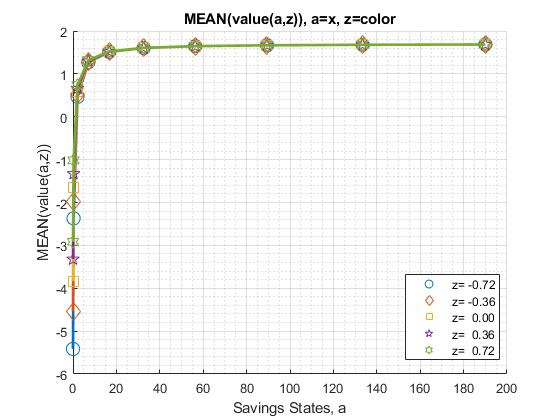

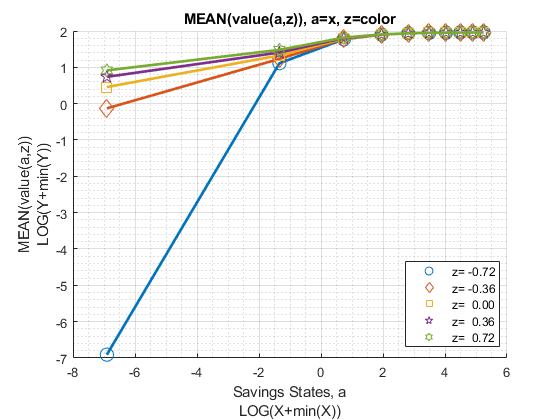

mp_support_graph('cl_st_graph_title') = {'MEAN(value(a,z)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(value(a,z))'};
ff_graph_grid((tb_az_v{1:end, 3:end})', eta_grid, agrid, mp_support_graph);

Graph Mean Savings Choices:

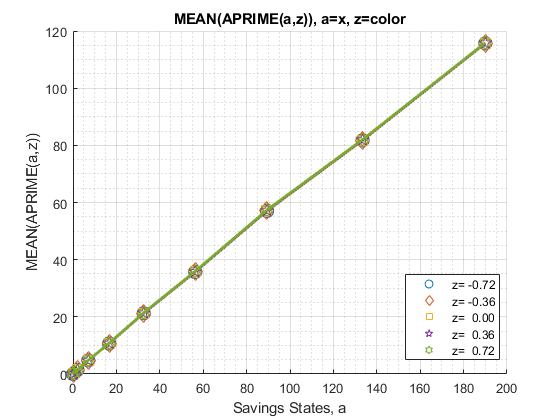

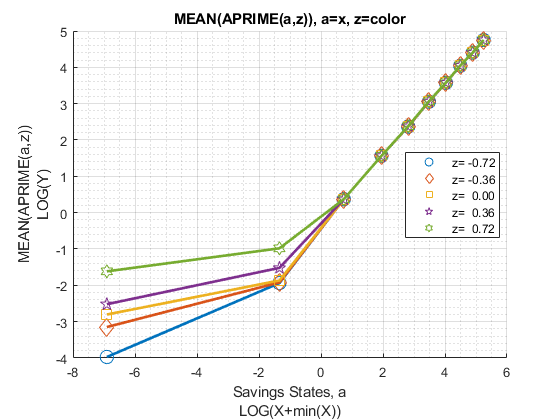

mp_support_graph('cl_st_graph_title') = {'MEAN(APRIME(a,z)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(APRIME(a,z))'};
ff_graph_grid((tb_az_ap{1:end, 3:end})', eta_grid, agrid, mp_support_graph);

Graph Mean Consumption:

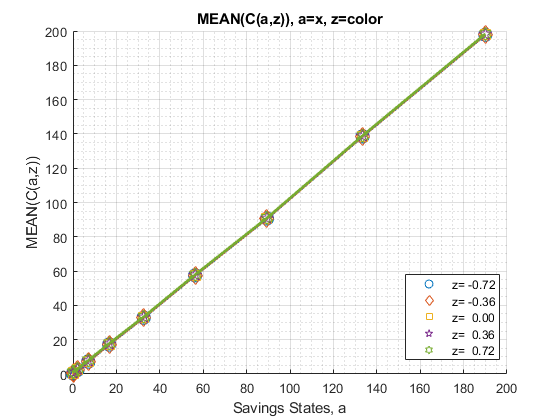

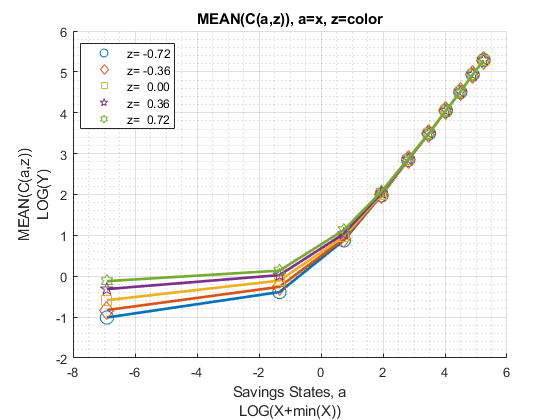

mp_support_graph('cl_st_graph_title') = {'MEAN(C(a,z)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(C(a,z))'};
ff_graph_grid((tb_az_c{1:end, 3:end})', eta_grid, agrid, mp_support_graph);

## Analyze Kids and Marriage and Age

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = ["k0M0", "K1M0", "K2M0", "k0M1", "K1M1", "K2M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = { 'o', 'd' ,'s', 'o', 'd', 's'};
mp_support_graph('cl_colors') = {'red', 'red', 'red', 'blue', 'blue', 'blue'};

#### MEAN(VAL(KM,J)), MEAN(AP(KM,J)), MEAN(C(KM,J))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,4,1,6,5];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(VAL(KM,J))", V_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(VAL(KM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ____    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       1        0         1.4934          1.493         1.3441         1.0186        0.37344         0.37209        0.37858  
      2       2        0         1.1256         1.2127         1.1142        0.79569       0.035681         0.10948        0.12118  
      3       3        0         0.8916        0.99118        0.90181        

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(AP(KM,J))", ap_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(AP(KM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ____    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       1        0        52.767         52.777          50.64         39.632         29.463         8.4444            0      
      2       2        0        52.768          52.78         48.711         37.523         27.128         8.4444            0      
      3       3        0        52.763         52.683         48.681         3

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(C(KM,J))", cons_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(C(KM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ____    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       1        0        34.848          35.08         37.478         48.451         57.791          78.81          87.254   
      2       2        0        34.847         35.078         39.407         50.561         60.127          78.81          87.254   
      3       3        0        34.852         35.175         39.436         50

Graph Mean Values:

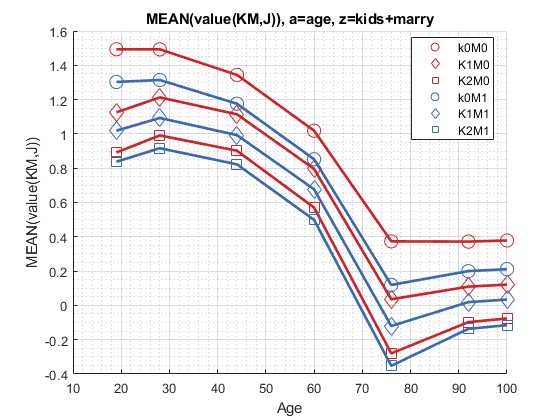

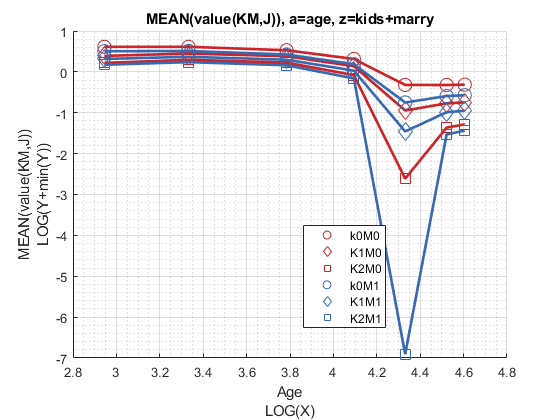

mp_support_graph('cl_st_graph_title') = {'MEAN(value(KM,J)), a=age, z=kids+marry'};
mp_support_graph('cl_st_ytitle') = {'MEAN(value(KM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Savings Choices:

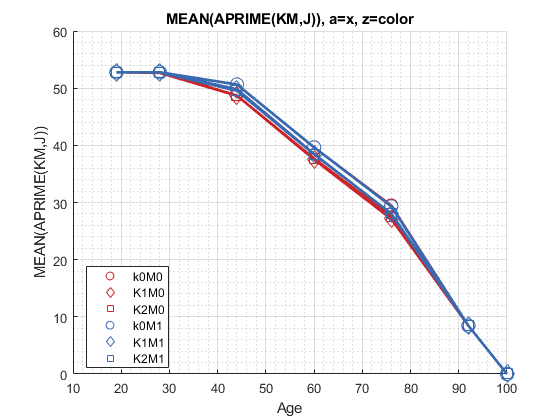

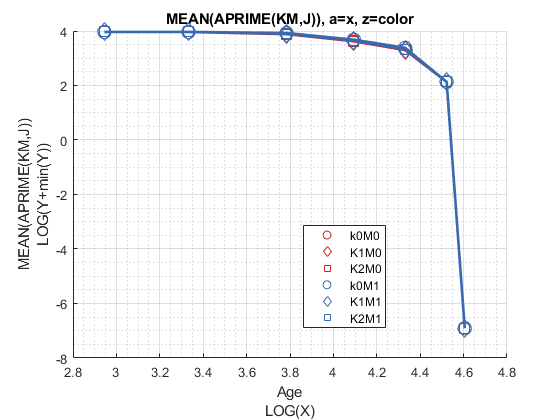

mp_support_graph('cl_st_graph_title') = {'MEAN(APRIME(KM,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(APRIME(KM,J))'};
ff_graph_grid((tb_az_ap{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption:

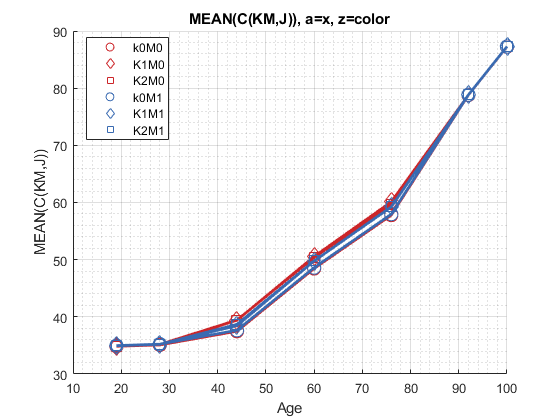

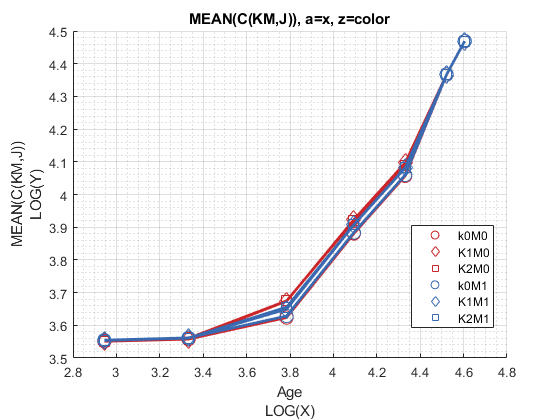

mp_support_graph('cl_st_graph_title') = {'MEAN(C(KM,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(C(KM,J))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

## Analyze Education and Marriage and Age

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = ["E0M0", "E1M0", "E0M1", "E1M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = {'*', 'p', '*','p' };
mp_support_graph('cl_colors') = {'red', 'red', 'blue', 'blue'};

#### MEAN(VAL(EKM,J)), MEAN(AP(EKM,J)), MEAN(C(EKM,J))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,6,1,4,5];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(VAL(EKM,J))", V_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(VAL(EKM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ___    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       0       0         1.1013         1.1307         1.0201        0.70553       -0.040411       0.069967       0.084943  
      2       1       0         1.2391         1.3339         1.2199        0.88415         0.12665        0.18613        0.19734  
      3       0       1        0.96683        0.99541        0.88675        0.57

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(AP(EKM,J))", ap_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(AP(EKM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ___    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       0       0        52.774         52.746         49.233         38.168         28.017         8.4444            0      
      2       1       0        52.759         52.747         49.456         38.394         28.084         8.4444            0      
      3       0       1        52.776         52.779         49.909         38.72

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(C(EKM,J))", cons_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(C(EKM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ___    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       0       0        34.841         35.012         38.703         49.751         59.219         78.792          87.236   
      2       1       0        34.856          35.21         38.845         49.855         59.189         78.828          87.273   
      3       0       1        34.936          35.09         38.151         49.328

Graph Mean Values:

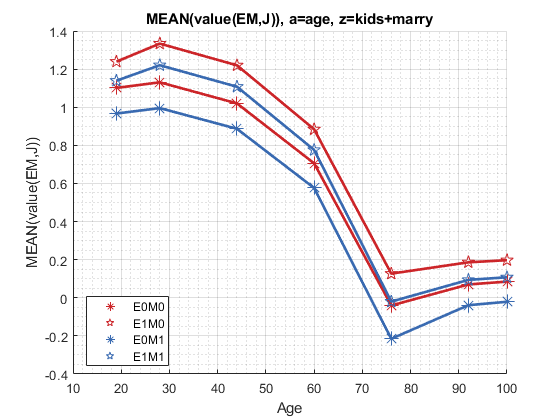

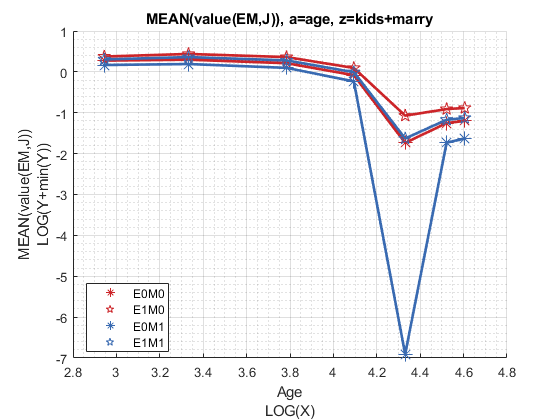

mp_support_graph('cl_st_graph_title') = {'MEAN(value(EM,J)), a=age, z=kids+marry'};
mp_support_graph('cl_st_ytitle') = {'MEAN(value(EM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Savings Choices:

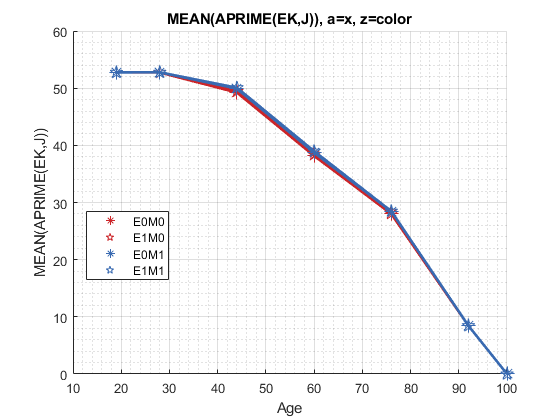

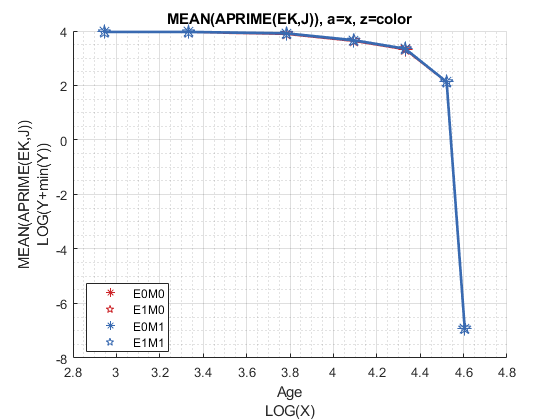

mp_support_graph('cl_st_graph_title') = {'MEAN(APRIME(EK,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(APRIME(EK,J))'};
ff_graph_grid((tb_az_ap{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption:

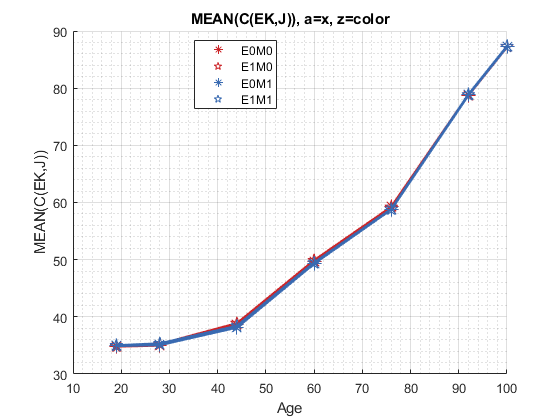

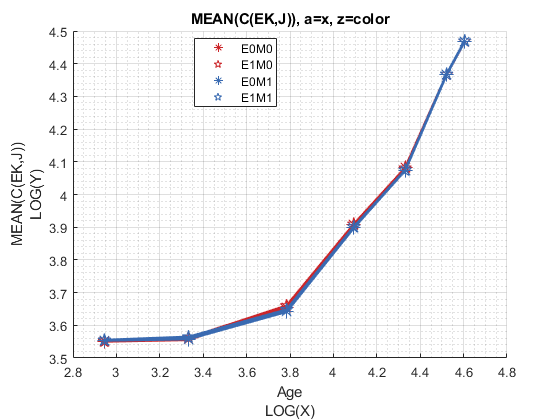

mp_support_graph('cl_st_graph_title') = {'MEAN(C(EK,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(C(EK,J))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);